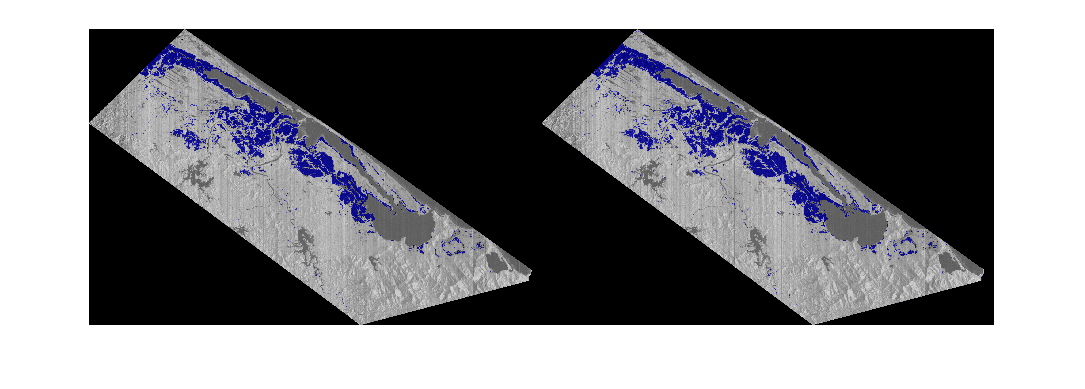

predictPatchSize = [1024 1024];
test_input = imread('D:\Download\hue-20201211T023421Z-001\hue\input_hue_1010.tif');
input = custominputreader(test_input);
nor_input = normalize(test_input(:,:,1), 'range', [0 1]);

test_label = imread('D:\Download\hue-20201211T023421Z-001\hue\label_hue_1010.tif');
l1 = double(test_label + 1);
b1 = labeloverlay(nor_input,l1,'ColorMap', [0.7 0.7 0.7; 0 0 1]);

output = segmentImage(input,trainedNetwork_1,predictPatchSize);
l2 = double(output);
b2 = labeloverlay(nor_input,l2,'ColorMap', [0.7 0.7 0.7; 0 0 1]);
imshow(cat(2,b1, b2));

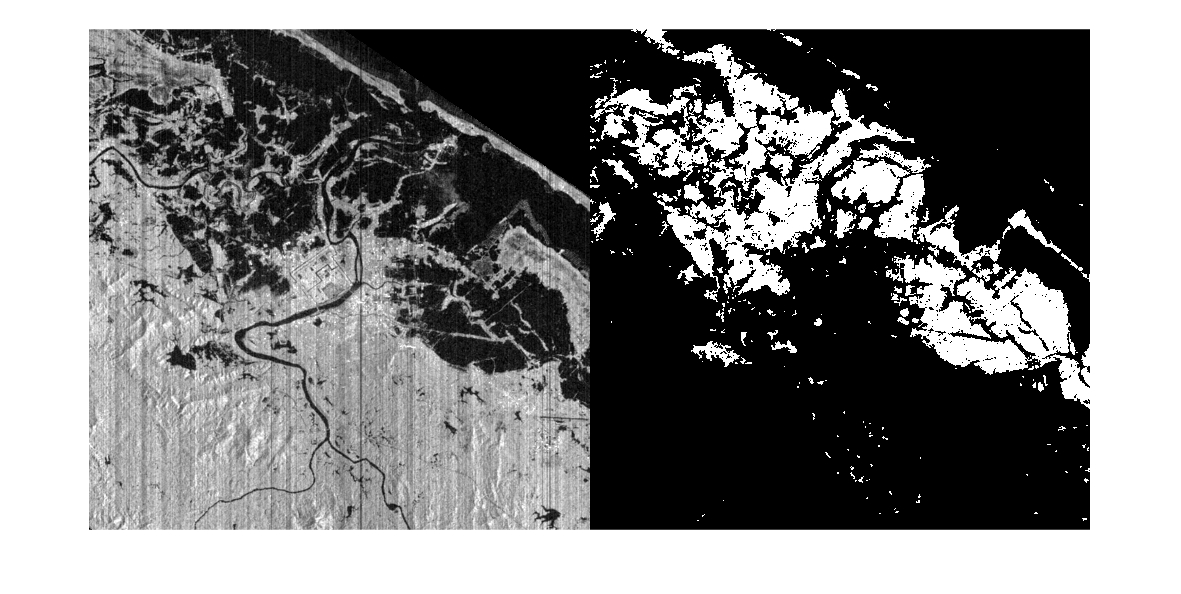

vc = nor_input(500:1500, 1000:2000);
lvc = normalize(l1(500:1500, 1000:2000), 'range', [0 1]);
imshow(cat(2, vc, lvc))

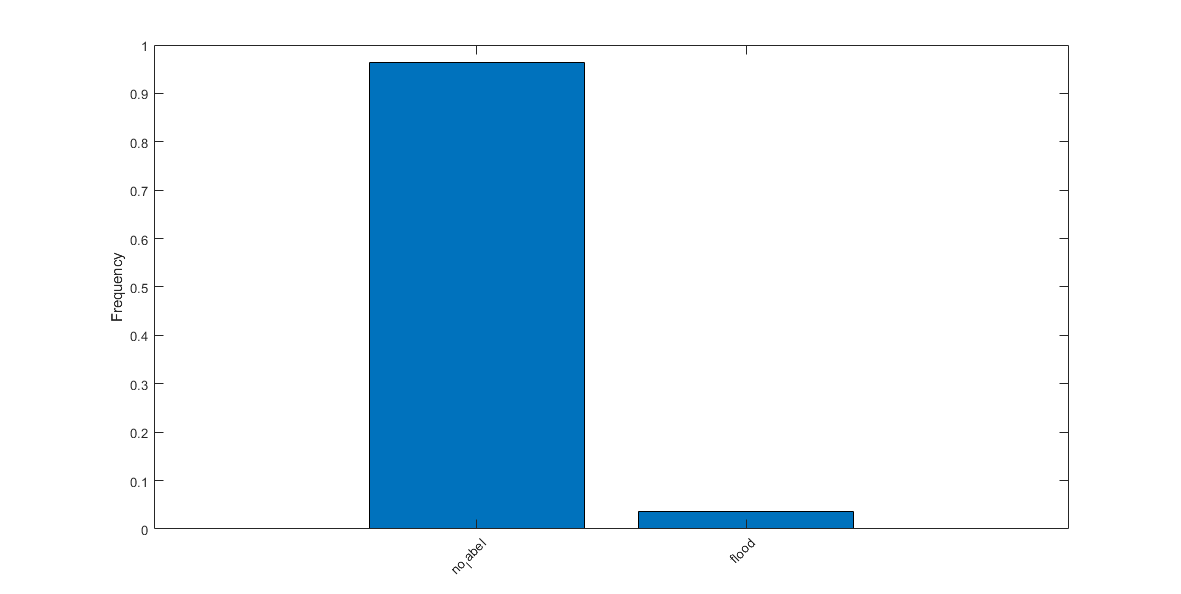

bar(1:numel(classes),frequency)
xticks(1:numel(classes))
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

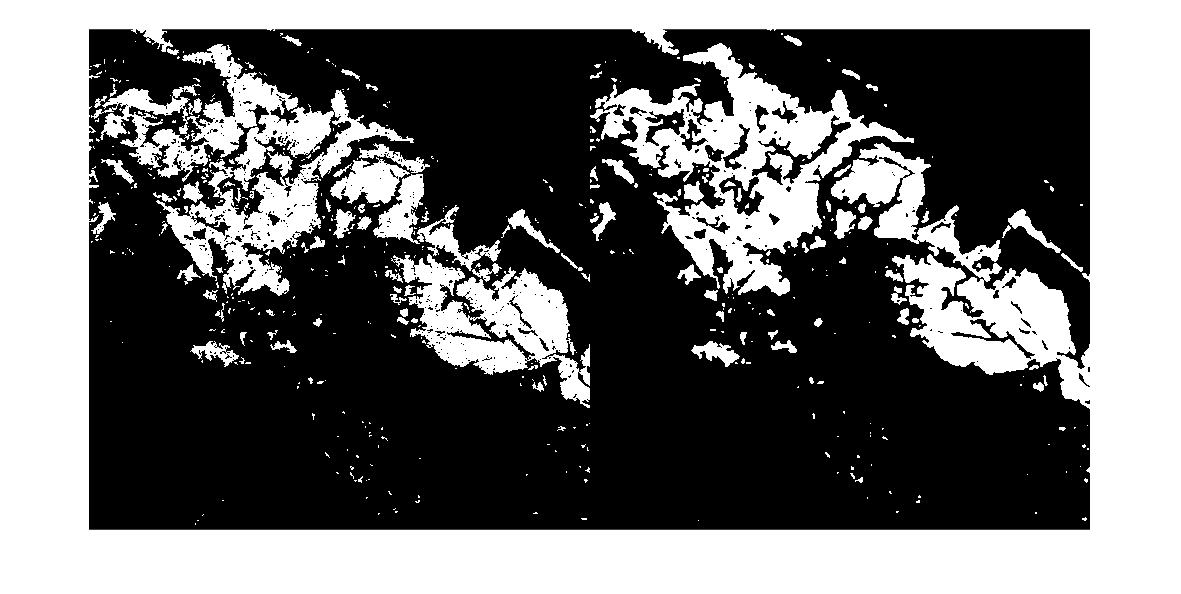

filllabeler =  @(image) customlabelreader(image, 0.35, 2);
lvc2 = filllabeler(lvc);
imshow(double(cat(2, lvc, lvc2)))